1. 表格中给出了2017年中国大陆各省（直辖市、自治区）城镇化相关数据，进行聚类分析，写出具体计算步骤，最后要对结果进行解释。

clear;clc;
X = readtable('课后作业数据.xlsx','ReadVariableNames',true,'VariableNamingRule','preserve');

% 标准差标准化数据矩阵
BX = zscore(table2array(X(:,3:end)),1);  

% 欧氏距离
Y1 = pdist(BX,'euclidean'); 
%转换成距离矩阵
SY1 = squareform(Y1);
% 最短距离法定义构建具层次结构的聚类树
Z11 = linkage(Y1,'single'); 
% 最长距离法定义构建具层次结构的聚类树
Z12 = linkage(Y1,'complete'); 
% 质心距离法定义构建具层次结构的聚类树
Z13 = linkage(Y1,'centroid');

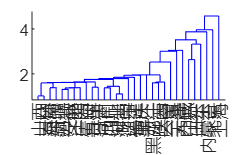

% 未加权平均距离法定义构建具层次结构的聚类树
Z14 = linkage(Y1,'average');
%检验一定算法下产生的二叉聚类树和实际情况的相符程度
C11 = cophenet(Z11,Y1);
C12 = cophenet(Z12,Y1);
C13 = cophenet(Z13,Y1);
C14 = cophenet(Z14,Y1);

% 曼哈顿距离
Y2 = pdist(BX, 'cityblock');
SY2 = squareform(Y2);
Z2 = linkage(Y2,'single'); 
C2 = cophenet(Z2,Y2);

%minkowski——明科夫斯基距离
Y3 = pdist(BX,'minkowski',2);
SY3 = squareform(Y3);
Z3 = linkage(Y3,'single'); 
C3 = cophenet(Z3,Y3);

%chebychev——切比雪夫距离
Y4 = pdist(BX, 'chebychev');
SY4 = squareform(Y4);
Z4 = linkage(Y4,'single'); 
C4 = cophenet(Z4,Y4);

% 选择欧氏距离 & 未加权平均距离法

T = cluster(Z14,3);  % 创建聚类
T = cluster(Z14,"criterion","distance","cutoff",3);
name = X.("地区");
[H,T,outperm] = dendrogram(Z11,31,'Labels',name'); % 画聚类图

2. 根据以上数据，进行主成分分析，并对结果进行解释。

clear;clc;

X = readtable('主成分数据.xlsx','ReadVariableNames',true,'VariableNamingRule','preserve');
mX = table2array(X);

% method 1 直接使用内置函数pca
    % coeff 主成分系数,行包含8个原料变量的系数，其列对应于8个主成分。
    % score  主成分分数
    % explained  解释方差占总方差的百分比
[coeff, score, ~, ~, explained, ~] = pca(mX);
% 计算主成分累积贡献率
latent = cumsum(explained);
% 取累计贡献率达85%的特征值所对应的主成分
i = find(latent >= 85, 1, 'first');
% 行包含8个原料变量的系数，其列对应于累计贡献率达85%的特征值所对应的主成分。
MainCoeff = coeff(1:i, :);

% method 2 自行编写函数
% % 极差标准化
% BX = (mX - min(mX)) ./ (max(mX) - min(mX));
% 标准差标准化数据矩阵
BX = zscore(mX,1);  
X.Properties.VariableNames

ans = 1×9 cell 数组
    {'人口密度x1/(人·.km-2)'}    {'人均耕地面积x 2/hm2)'}    {'森林覆盖率x3/%'}    {'农民人均纯收入x4/(元·人-1)'}    {'人均粮食产量x5 (kg·人-1)'}    {'经济作物占农作物播面比例x6/％'}    {'耕地占土地面积比x7/％'}    {'果园与林地面积之比x8/％'}    {'灌溉田占耕地面积之比x9/％'}


% 计算相关系数矩阵
R = corrcoef(BX); 
% 计算特征值(对角矩阵 D)和特征向量(矩阵 V)
[V, D] = eig(R); 
% 从对角矩阵D中提取特征值
d = diag(D); 
% 对特征根进行排序
[d, ind] = sort(d,'descend');
% 使用 ind 对 D 的对角线元素进行重新排序。
Ds = D(ind, ind);
% 使用相同的索引 ind 对 V 的列进行重新排序。
Vs = V(:, ind);

% 计算主成分贡献率
latent = d / sum(d); 
% 计算主成分累计贡献率
Latent = cumsum(latent);  
% 取累计贡献率达 85% 的特征值所对应的主成分
i = find(Latent >= 0.85,1,'first');
% 主成分载荷
B = sqrt(d(1:i)') .* Vs(:,1:i); 
% 主成分得分
C = mX * B;  